# EL2520 Computer Exercise 2

## 3.2 Decentralized Control

s = tf('s');
sys = minphase;

A = sys.A;
B = sys.B;
C = sys.C;
D = sys.D;

I = eye(size(A,1));
G = C*inv(s*I-A)*B+D; % 2x2 trans. func.


### 3.2.1 | Decentralized controller design

% Design criteria
w_cd = 0.1; % omega_c,d [rad/s]
p_m = pi/3; % phi_m [rad]

g11 = G(1,1);
g22 = G(2,2);

[m11,p11] = bode(g11, w_cd); % Amplitude and phase of system at w_cd
[m22,p22] = bode(g22, w_cd); % Amplitude and phase of system at w_cd

T11 = (1/w_cd)*tan(-pi + pi/2 + p_m - deg2rad(p11)); 
T22 = (1/w_cd)*tan(-pi + pi/2 + p_m - deg2rad(p22));

l11 = g11*(1 + 1/(s*T11));
l22 = g22*(1 + 1/(s*T22));

[m1, p1] = bode(l11,w_cd);
[m2, p2] = bode(l22,w_cd);

K1 = 1/m1;
K2 = 1/m2;

f1 = K1*(1+(1/(s*T11)));
f2 = K2*(1+(1/(s*T22)));

F = [f1, 0; 0, f2]

[Gm,Pm,wp,wc] = margin(f1*g11) % Phase margin, amplitude margin, and corresp. freqs. of G_d
[Gm,Pm,wp,wc] = margin(f2*g22) % Phase margin, amplitude margin, and corresp. freqs. of G_d

### 3.2.2 | Sensitivity and robustness

I = eye(size(G,1));

S = minreal(inv(I + G*F));
T = minreal(S*G*F);

max(sigma(S))
sigma(T)



### 3.2.3 | Closed loop simulation

closedloop


### 3.2.4 - Non-minimum phase case

s = tf('s');
sys = nonminphase; % 3.2.4

A = sys.A;
B = sys.B;
C = sys.C;
D = sys.D;

I = eye(size(A,1));
G = C*inv(s*I-A)*B+D; % 2x2 trans. func.

p_m = pi/3;
w_cd = 0.02; % rad/s

g12 = G(1,2); % For designing f2
g21 = G(2,1); % For designing f1

[m12,p12] = bode(g12, w_cd); % Amplitude and phase of system at w_cd
[m21,p21] = bode(g21, w_cd); % Amplitude and phase of system at w_cd

T1 = (1/w_cd)*tan(-pi + pi/2 + p_m - deg2rad(p21)) % G21 -> T1

T1 = 4.8107

T2 = (1/w_cd)*tan(-pi + pi/2 + p_m - deg2rad(p12)) % G12 -> T2

T2 = 3.9426


l21 = g21*(1 + 1/(s*T1));
l12 = g12*(1 + 1/(s*T2));

[m1, p1] = bode(l21,w_cd); % G21 -> f1
[m2, p2] = bode(l12,w_cd); % G12 -> f2

K1 = 1/m1

K1 = 0.1437

K2 = 1/m2

K2 = 0.1469


f1 = K1*(1+(1/(s*T1)));
f2 = K2*(1+(1/(s*T2)));

F = [0, f1; f2, 0];

L = G*F


L =
 
  From input 1 to output...
             0.001498 s + 0.0003799
   1:  ----------------------------------
       3.943 s^3 + 0.5397 s^2 + 0.01728 s
 
       0.01047 s + 0.002656
   2:  --------------------
       3.943 s^2 + 0.185 s
 
  From input 2 to output...
       0.01444 s + 0.003001
   1:  --------------------
       4.811 s^2 + 0.2456 s
 
            0.002187 s + 0.0004546
   2:  ---------------------------------
       4.811 s^3 + 0.663 s^2 + 0.02052 s
 
Continuous-time transfer function.




% L(1,1) = g12*f2

Gm = 13.5243

Pm = 60.0001

wp = 0.0976

wc = 0.0200

[Gm,Pm,wp,wc] = margin(L(1,1)) % Phase margin, amplitude margin, and corresp. freqs. of G_d

Gm = 13.5243

Pm = 60.0001

wp = 0.0976

wc = 0.0200


% L(2,2) = g21*f1

Gm = 18.4662

Pm = 60.0001

wp = 0.1125

wc = 0.0200

[Gm,Pm,wp,wc] = margin(L(2,2)) % Phase margin, amplitude margin, and corresp. freqs. of G_d

Gm = 18.4662

Pm = 60.0001

wp = 0.1125

wc = 0.0200

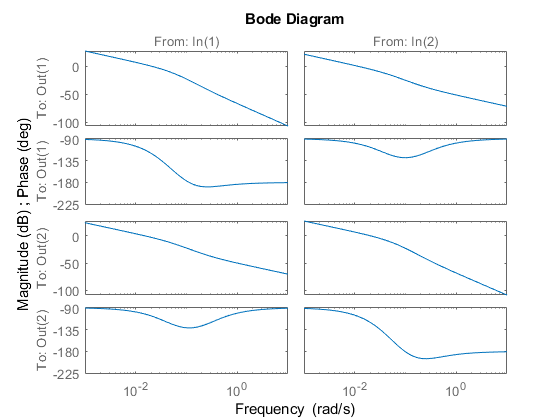


bode(F*G)